fo = fopen('4.txt', 'r');

raw_text = fscanf(fo, '%c');

list_text = strsplit(raw_text, '\n');

X = [];
Y = [];
Z = [];

for el = list_text
   tmp = char(el);
   if tmp(1) == '('
       strip_left  = strip(el, '(');
       cleaned = strip(strip_left, ')');
       splited = split(cleaned, ', ');
       X(end + 1) = str2double(splited(1));
       Y(end + 1) = str2double(splited(2));
       Z(end + 1) = str2double(splited(3));
   end
end

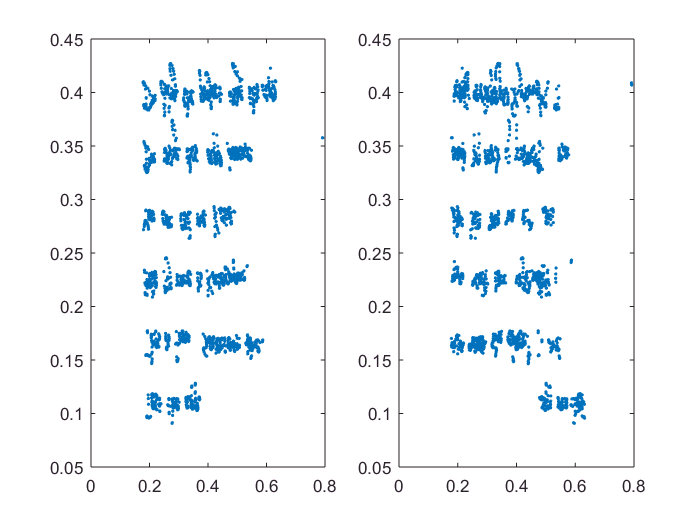

figure;
subplot(1,2,1); plot(X,Y, '.');
subplot(1,2,2); plot(Y,X, '.');